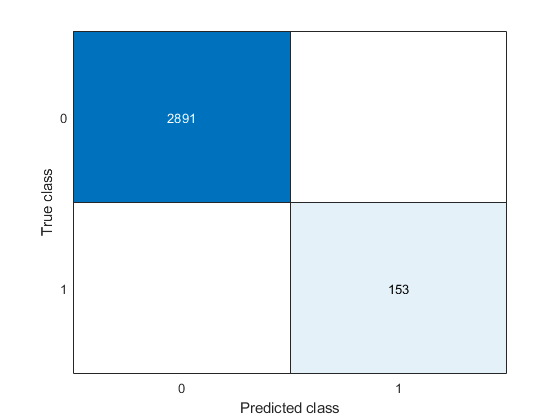

clc;
clear;

% 1. Es creen els dataSets --> executar createDatasets.m (19 segons)

% 2. Fem el training dels ulls --> executar eye_training.m (392 segons)

TData = load('data\TrainData.mat');
trainingEyes = TData.trainingEyes;   
trainingNotEyes = TData.trainingNotEyes;

% 3. Fem el testing dels ulls

ClassifierEyes = load('data\eyeClassifier.mat');
TestData = load('data\TestData.mat');
testingEyes = TestData.testingEyes;
testingNotEyes = TestData.testingNotEyes;
eyeClassifier = ClassifierEyes.eyeClassifier;
[predictor, cmatrix] = eye_testing();


% 4. Fem el training de mirades

expectedLabels = xlsread("data\Miram.xlsx", 1, "E5:E1525");

% 5. Fem el testing de mirades


